# Zadanie 6 - Liczenie grubości cienkiej warstwy $\mathrm{Si}O_2$ na podstawie pomiaru i zananych współczynników załmania

Najpierw wczytuje się pliki z współczynnikami załamania od długości fali i plik pomiaru odbicia

clc; clear all;

fprintf("wczytaj plik z współczynnikiem załamania od długości fali dla Si");

wczytaj plik z współczynnikiem załamania od długości fali dla Si

[file,path]=uigetfile('*.txt');
if file==0
    disp('User selected Cancel')
else 
    disp(['User selected',fullfile(path,file)])
end

User selectedF:\nauka\pwr\rok 3 semestr 6(letni)\Metody Symulacji Fotoogniw - Labolatorium\Si.txt



cd(path);
fileID=fopen(file);
data=textscan(fileID,'%f%f');
lambda_Si=data{1};%[nm]
lambda_Si=lambda_Si*1000;
n_Si=data{2};%[]

%%%%%%%%%%

fprintf("wczytaj plik z współczynnikiem załamania od długości fali dla SiO2");

wczytaj plik z współczynnikiem załamania od długości fali dla SiO2

[file,path]=uigetfile('*.txt');
if file==0
    disp('User selected Cancel')
else 
    disp(['User selected',fullfile(path,file)])
end

User selectedF:\nauka\pwr\rok 3 semestr 6(letni)\Metody Symulacji Fotoogniw - Labolatorium\SiO2.txt



cd(path);
fileID=fopen(file);
data=textscan(fileID,'%f%f');
lambda_SiO2=data{1};%[nm]
n_SiO2=data{2};%[]

%%%%%%%%%%%%

fprintf("wczytaj plik z współczynnikiem odbicia od długości fali dla modelu");

wczytaj plik z współczynnikiem odbicia od długości fali dla modelu

[file,path]=uigetfile('*.txt');
if file==0
    disp('User selected Cancel')
else 
    disp(['User selected',fullfile(path,file)])
end

User selectedF:\nauka\pwr\rok 3 semestr 6(letni)\Metody Symulacji Fotoogniw - Labolatorium\Reflection.txt



cd(path);
fileID=fopen(file);
data=textscan(fileID,'%f%f');
lambda=data{1};%[nm]
n_ref=data{2};%[]

Następnie przedstawino wczytane dane na wykresach.

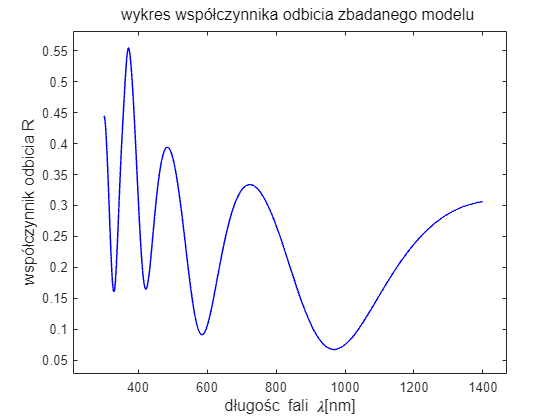

%%%%%%%%%%%%%%%%%%%

plot(lambda,n_ref,'color','blue','Linewidth',1.1)
zak_lam=max(abs(lambda));
xlim([zak_lam*0.15,zak_lam*1.05]);
zak_nr=max(abs(n_ref));
ylim([zak_nr*0.05,zak_nr*1.05]);
xlabel("długośc fali \lambda[nm]","FontSize",12);
ylabel("współczynnik odbicia R","FontSize",12);
text(zak_lam*0.25, zak_nr*1.1,'wykres współczynnika odbicia zbadanego modelu','FontSize', 12);

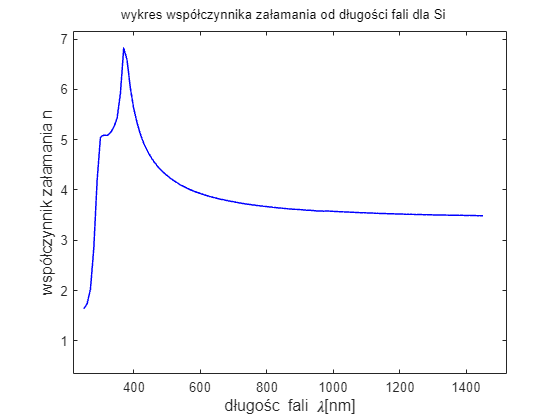


%%%%%%%%%%%%%%%%%%%%%%%

plot(lambda_Si,n_Si,'color','blue','Linewidth',1.1)
zak_lam=max(abs(lambda_Si));
xlim([zak_lam*0.15,zak_lam*1.05]);
zak_nr=max(abs(n_Si));
ylim([zak_nr*0.05,zak_nr*1.05]);
xlabel("długośc fali \lambda[nm]","FontSize",12);
ylabel("współczynnik załamania n","FontSize",12);
text(zak_lam*0.25, zak_nr*1.1,'wykres współczynnika załamania od długości fali dla Si','FontSize', 10);

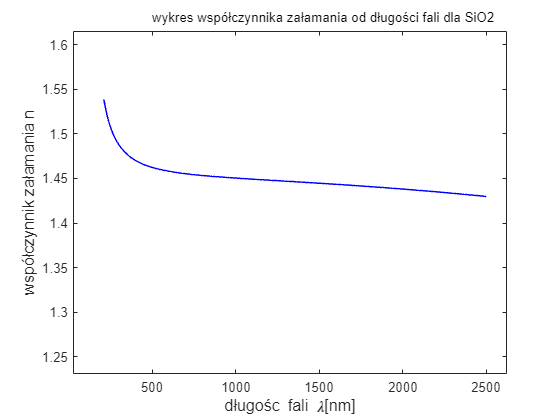


%%%%%%%%%%%%%%%%%%%%%%%%%%%

plot(lambda_SiO2,n_SiO2,'color','blue','Linewidth',1.1)
zak_lam=max(abs(lambda_SiO2));
xlim([zak_lam*0.01,zak_lam*1.05]);
zak_nr=max(abs(n_SiO2));
ylim([zak_nr*0.8,zak_nr*1.05]);
xlabel("długośc fali \lambda[nm]","FontSize",12);
ylabel("współczynnik załamania n","FontSize",12);
text(zak_lam*0.2, zak_nr*1.06,'wykres współczynnika załamania od długości fali dla SiO2','FontSize', 10);

Następnie zinterpolowano te dane dla zakresu argumentów danych z pomiaru współczynnika odbicia od długości fali.

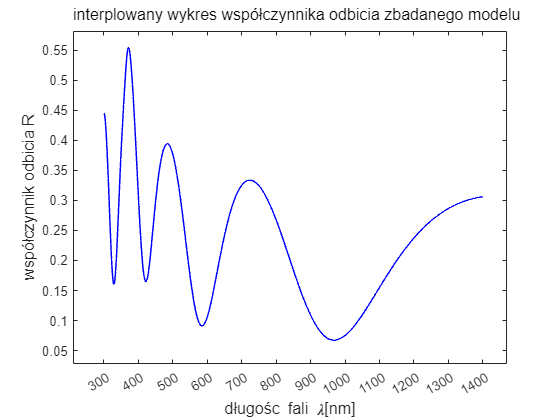

%%%%%%%%%%%%%%%%%%%%%%%%

in_lamb=min(lambda):0.01:max(lambda);
inter_n_Si=interp1(lambda_Si,n_Si,in_lamb,"spline");
inter_n_SiO2=interp1(lambda_SiO2,n_SiO2,in_lamb,"spline");
inter_n_ref=interp1(lambda,n_ref,in_lamb,"spline");

%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%

plot(in_lamb,inter_n_ref,'color','blue','Linewidth',1.1)
zak_lam=max(abs(in_lamb));
xlim([zak_lam*0.15,zak_lam*1.05]);
xticks(200:100:1400);
zak_nr=max(abs(inter_n_ref));
ylim([zak_nr*0.05,zak_nr*1.05]);
xlabel("długośc fali \lambda[nm]","FontSize",12);
ylabel("współczynnik odbicia R","FontSize",12);
text(zak_lam*0.15, zak_nr*1.1,'interplowany wykres współczynnika odbicia zbadanego modelu','FontSize', 12);

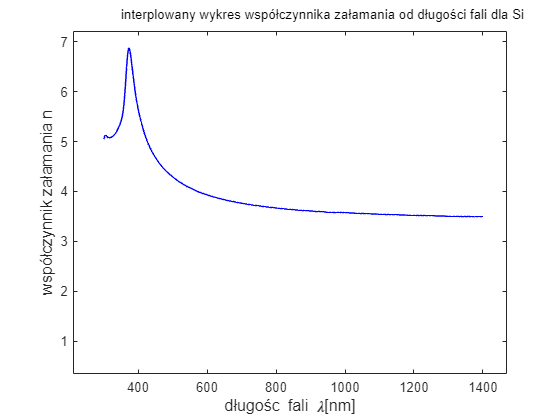


%%%%%%%%%%%%%%%%%%%%%%%

plot(in_lamb,inter_n_Si,'color','blue','Linewidth',1.1)
xlim([zak_lam*0.15,zak_lam*1.05]);
zak_nr=max(abs(inter_n_Si));
ylim([zak_nr*0.05,zak_nr*1.05]);
xlabel("długośc fali \lambda[nm]","FontSize",12);
ylabel("współczynnik załamania n","FontSize",12);
text(zak_lam*0.25, zak_nr*1.1,'interplowany wykres współczynnika załamania od długości fali dla Si','FontSize', 10);

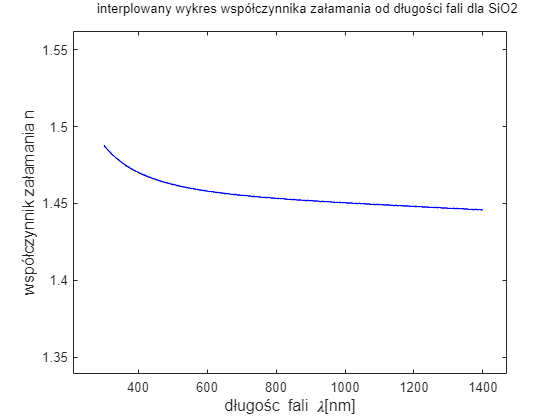


%%%%%%%%%%%%%%%%%%%%%%%%%%%

plot(in_lamb,inter_n_SiO2,'color','blue','Linewidth',1.1)
xlim([zak_lam*0.15,zak_lam*1.05]);
zak_nr=max(abs(inter_n_SiO2));
ylim([zak_nr*0.9,zak_nr*1.05]);
xlabel("długośc fali \lambda[nm]","FontSize",12);
ylabel("współczynnik załamania n","FontSize",12);
text(zak_lam*0.2, zak_nr*1.06,'interplowany wykres współczynnika załamania od długości fali dla SiO2','FontSize', 10);

Aby znaleść minima funkcji współczynnika odbicia R, policzono pochądną i przedstawiono ją na wykresie.

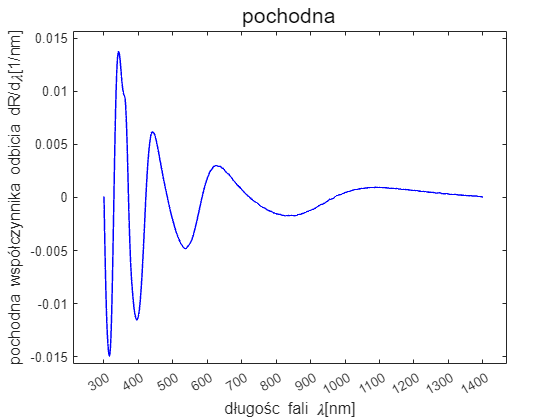

%%%%%%%%%%%%%%%%%%%%%%%%

len=size(inter_n_ref);
dRdl=zeros(1,len(2));     
for i=2:len(2)-1
    dRdl(1,i)=(inter_n_ref(1,i+1)-inter_n_ref(1,i-1))/(in_lamb(1,i+1)-in_lamb(1,i-1));
end    
dRdl(1,1)=dRdl(1,2);
dRdl(1,len(2))=dRdl(1,len(2)-1);

plot(in_lamb,dRdl,'color','blue','Linewidth',1.1)
xlim([zak_lam*0.15,zak_lam*1.05]);
xticks(200:100:1400);
zak_drdl=max(abs(dRdl));
ylim([-zak_drdl*1.05,zak_drdl*1.05]);
xlabel("długośc fali \lambda[nm]","FontSize",12);
ylabel("pochodna współczynnika odbicia dR/d\lambda[1/nm]","FontSize",12);
text(zak_lam*0.5, zak_drdl*1.15,'pochodna','FontSize', 16);

Następnnie metodą bisekcji znaleziono wszystkie zera odpowiadające minimom(destruktywne długości) i maksimom(konstruktywne długośći).

%%%% znajdywanie miejsc zerowych

maxs=zeros(1);
mins=zeros(1);

subsetx=in_lamb(FCNI(in_lamb,1100):FCNI(in_lamb,1400));
subsety=dRdl(FCNI(in_lamb,1100):FCNI(in_lamb,1400));

maxs(1,1)=bisection(subsetx,subsety,1e-6);

subsetx=in_lamb(FCNI(in_lamb,800):FCNI(in_lamb,1200));
subsety=dRdl(FCNI(in_lamb,800):FCNI(in_lamb,1200));
mins(1,1)=bisection(subsetx,subsety,1e-6);

subsetx=in_lamb(FCNI(in_lamb,650):FCNI(in_lamb,800));
subsety=dRdl(FCNI(in_lamb,650):FCNI(in_lamb,800));
maxs=[maxs,bisection(subsetx,subsety,1e-6)];

subsetx=in_lamb(FCNI(in_lamb,550):FCNI(in_lamb,600));
subsety=dRdl(FCNI(in_lamb,550):FCNI(in_lamb,600));
mins=[mins,bisection(subsetx,subsety,1e-6)];

subsetx=in_lamb(FCNI(in_lamb,450):FCNI(in_lamb,500));
subsety=dRdl(FCNI(in_lamb,450):FCNI(in_lamb,500));
maxs=[maxs,bisection(subsetx,subsety,1e-6)];

subsetx=in_lamb(FCNI(in_lamb,400):FCNI(in_lamb,450));
subsety=dRdl(FCNI(in_lamb,400):FCNI(in_lamb,450));
mins=[mins,bisection(subsetx,subsety,1e-6)];

subsetx=in_lamb(FCNI(in_lamb,340):FCNI(in_lamb,400));
subsety=dRdl(FCNI(in_lamb,340):FCNI(in_lamb,400));
maxs=[maxs,bisection(subsetx,subsety,1e-6)];

subsetx=in_lamb(FCNI(in_lamb,310):FCNI(in_lamb,340));
subsety=dRdl(FCNI(in_lamb,310):FCNI(in_lamb,340));
mins=[mins,bisection(subsetx,subsety,1e-6)];

subsetx=in_lamb(FCNI(in_lamb,300):FCNI(in_lamb,320));
subsety=dRdl(FCNI(in_lamb,300):FCNI(in_lamb,320));
maxs=[maxs,bisection(subsetx,subsety,1e-6)];

%plot(subsetx,subsety)


Znalezione długości fal(w nm) odpowiadające minimom:

disp(mins)

  968.7950  584.4950  421.5050  328.7650



Znalezione długości fal(w nm) odpowiadające maksimom:

format short g
disp(maxs)

         1400       723.49       484.07       371.09       300.05



format default

Rzędy prażka wyliczyone za pomocą pierwszej i drugiej długości, odpowiednio mk ze wzoru dla konstruktywnych długości i md dla destruktywnych.

mk=maxs(1,2)/(maxs(1,1)-maxs(1,2))

mk = 1.0695

md=(3*mins(1,2)-mins(1,1))/2/(mins(1,1)-mins(1,2))

md = 1.0209

Nasepnie policzono grubość warstwy w nano metrach, gdzie dk z długości konstruktywnych a dd z długości destruktywnych.

dk=mk*maxs(1,1)/(2*inter_n_SiO2(FCNI(in_lamb,maxs(1,1)))) %[1*nm/1=nm]

dk = 517.7908

dd=(md+0.5)*mins(1,1)/(2*inter_n_SiO2(FCNI(in_lamb,mins(1,1)))) %[1*nm/1=nm]

dd = 507.8113

Różnica między otrzymanymi wynikami procentowo:

uncert=(dk-dd)/dk*100

uncert = 1.9273


%z uwagi na to ze z rachunku na rzad prazka wychodzi ze 
% te maks musza sie wliczac dalaczam je by rzedy
%destruktywne i konstruktywne sie zgadzaly
%taki sam test zrobiono dla 300
% tu był test i ta końcówka jest zbyt daleko od zera w
% porówniau do reszty zer aby uznać to za maks
% zera dla pochodnej mają tolerancje około 1e-7
% a w 1400 mam około 1e-5


%
%disp(dRdl(FCNI(in_lamb,mins)))
%disp(dRdl(FCNI(in_lamb,bisection(in_lamb,dRdl,1e-6))))




 function [zero] = bisection(x, y, tolerance)
    % Check if the vectors have the same length
    if numel(x) ~= numel(y)
        error('The input vectors must have the same length.');
    end
    
    % Check if the vectors are sorted in ascending order
    if any(diff(x) < 0)
        error('The input vector x must be sorted in ascending order.');
    end
    
    % Initialize the lower and upper bounds
    lower = x(1);
    upper = x(end);
    
    % Perform bisection until the desired tolerance is achieved
    while (upper - lower) > tolerance
        % Calculate the midpoint
        midpoint = (lower + upper) / 2;
        
        % Find the indices of the two closest x values
        [~, index1] = min(abs(x - midpoint));
        [~, index2] = min(abs(x - lower));
        
        % Calculate the y values at the indices
        y1 = y(index1);
        y2 = y(index2);
        
        % Update the bounds based on the signs of the y values
        if sign(y1) == sign(y2)
            lower = midpoint;
        else
            upper = midpoint;
        end
    end
    
    % Return the zero
    zero = (lower + upper) / 2;
 end
 function index = FCNI(array, target)
    % Initialize variables
    minDiff = abs(array(1) - target);
    index = 1;
    
    % Find the index with the closest number
    for i = 2:length(array)
        diff = abs(array(i) - target);
        if diff < minDiff
            minDiff = diff;
            index = i;
        end
    end
end